# Distortion, noise, and strain

In this live script, the developments in all the previous major scripts will be applied to study the effects of noise in elucidating the total distortion using the Lawler-Fujita algorithm and how this combination affects the calculated physical strain according to Gao et al. (2017)'s method.

Let's define the initial parameters. If new to this live script, I suggest you change the values here and here only.

image_length = 256; % [pixel]
image_height = 256; % [pixel]
atom_diameter = 8; % [pixel]

lambda = 0.2; % [atom^-1]
lambda = lambda*2*pi/atom_diameter;

Q_x = [1 0]; % [atom^-1]
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

confidence_level = 0.9999999;
zscore = zscorer(confidence_level);

## 1    Adding distortion

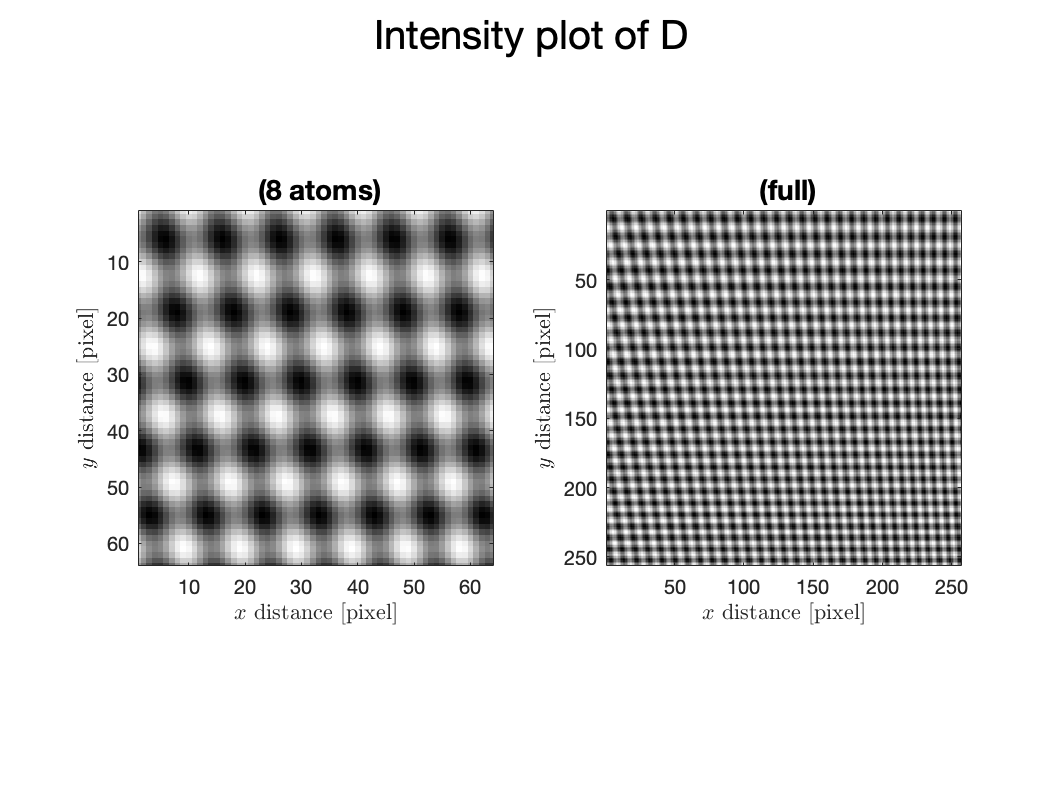

u = uCreate(image_height,image_length,atom_diameter,[4 4],[1 1],[4 2]);

lattice = normies(uTransform(u,Q_x,Q_y))*atom_diameter/2; % check the sign of u in uTransform()
comboPlot(lattice,"D",atom_diameter);

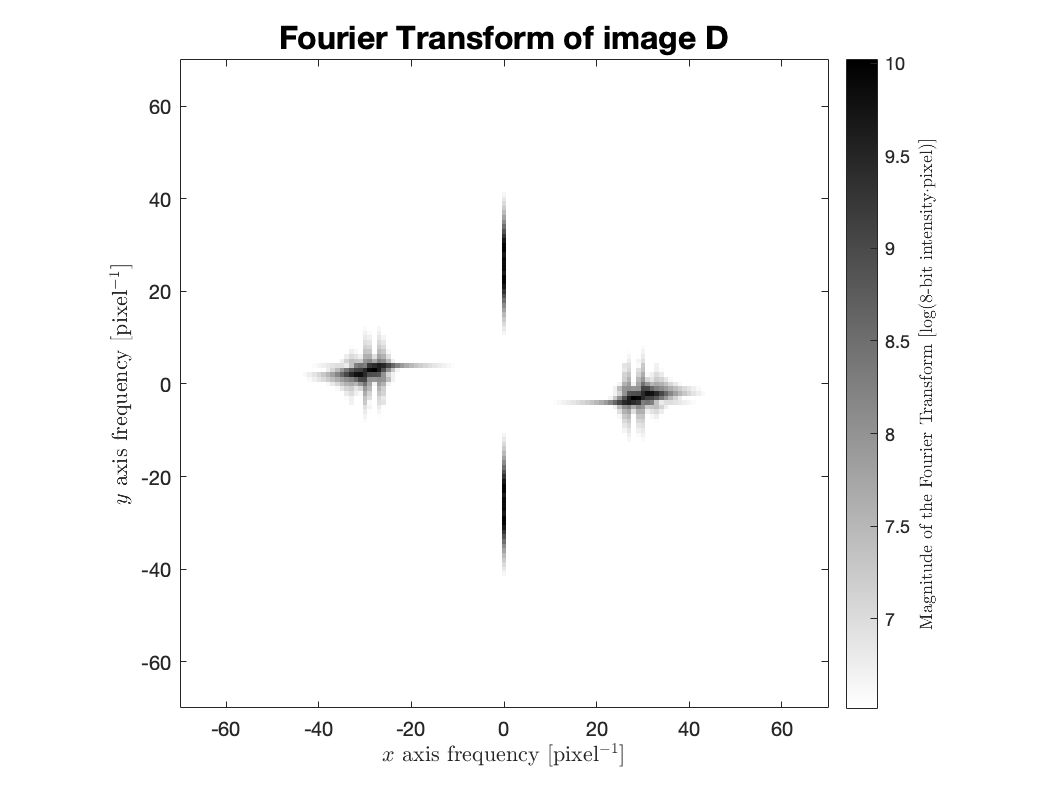

lattice_fft = myFFT(lattice,"D");

## 2    Adding noise

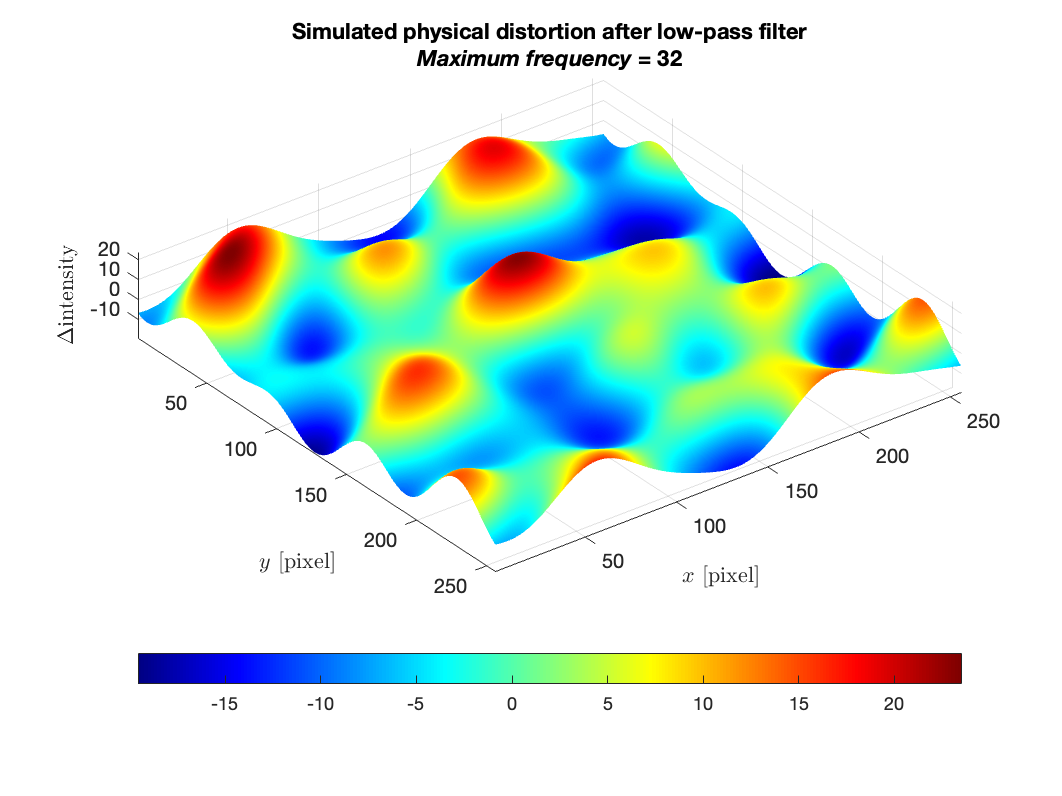

noise = noiseCreate(image_height,image_length,atom_diameter,10,1); % minl, mag
noisePlot(image_height,image_length,noise,[],atom_diameter);

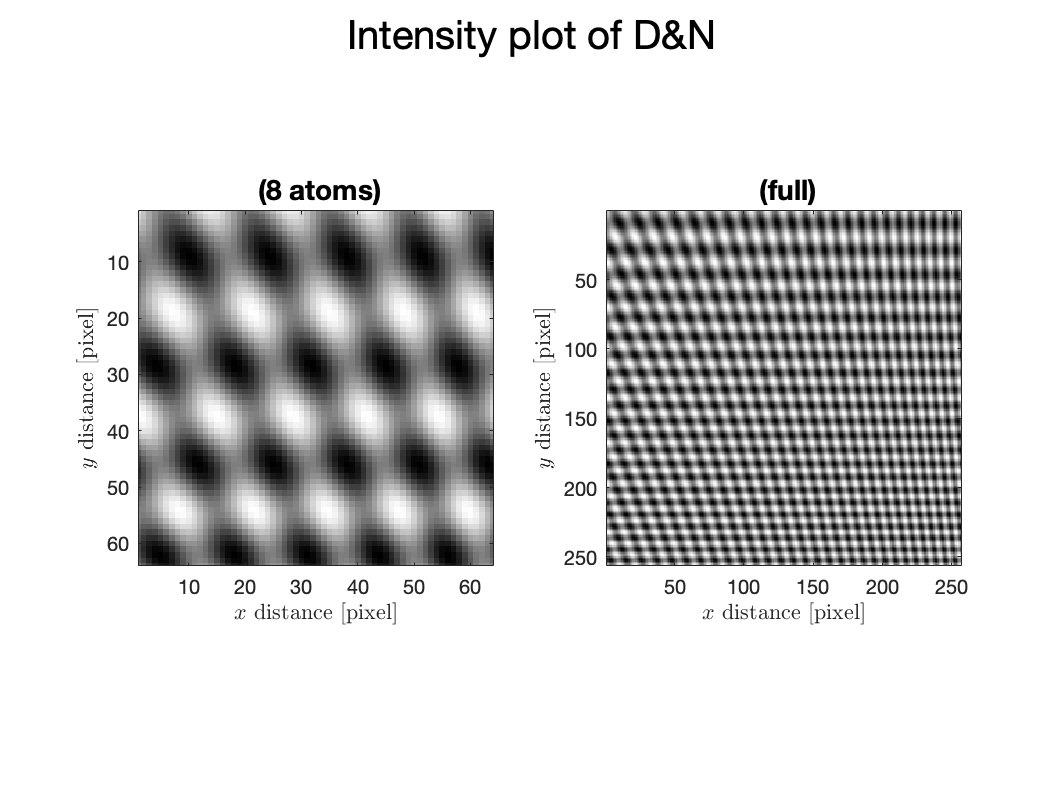


nlattice = lattice+noise;
comboPlot(nlattice,"D&N",atom_diameter);

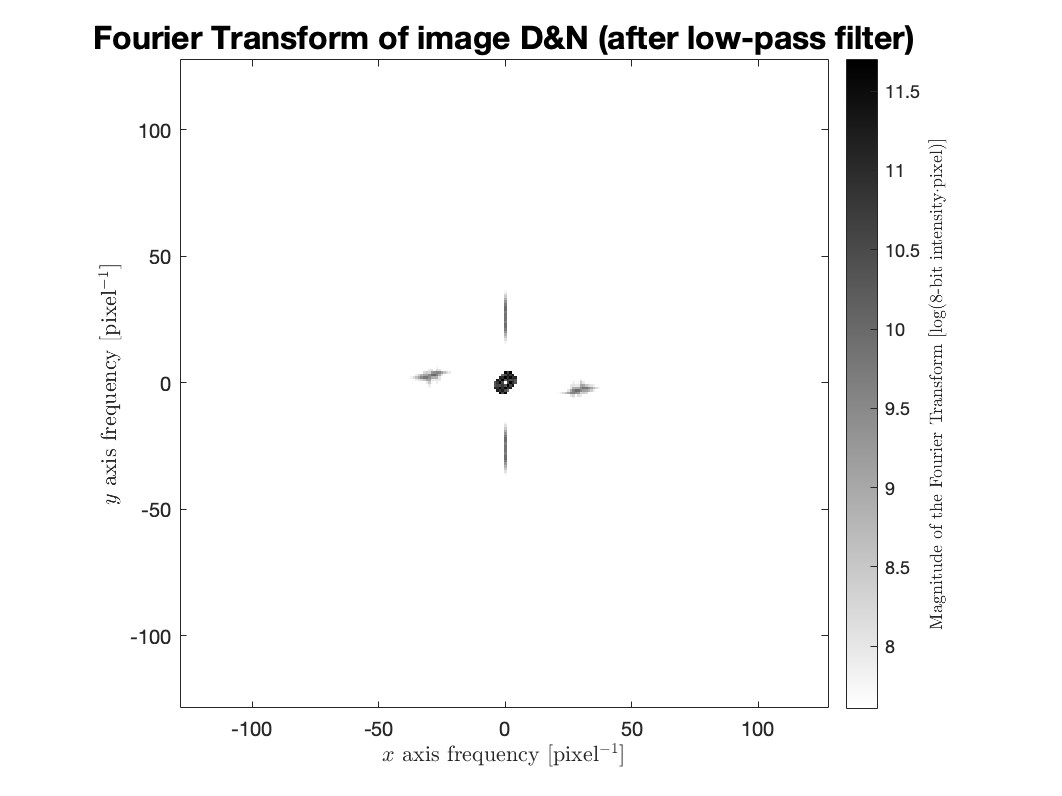

nlattice_fft = myFFT(nlattice,"D&N",[],atom_diameter/100); % just for full display

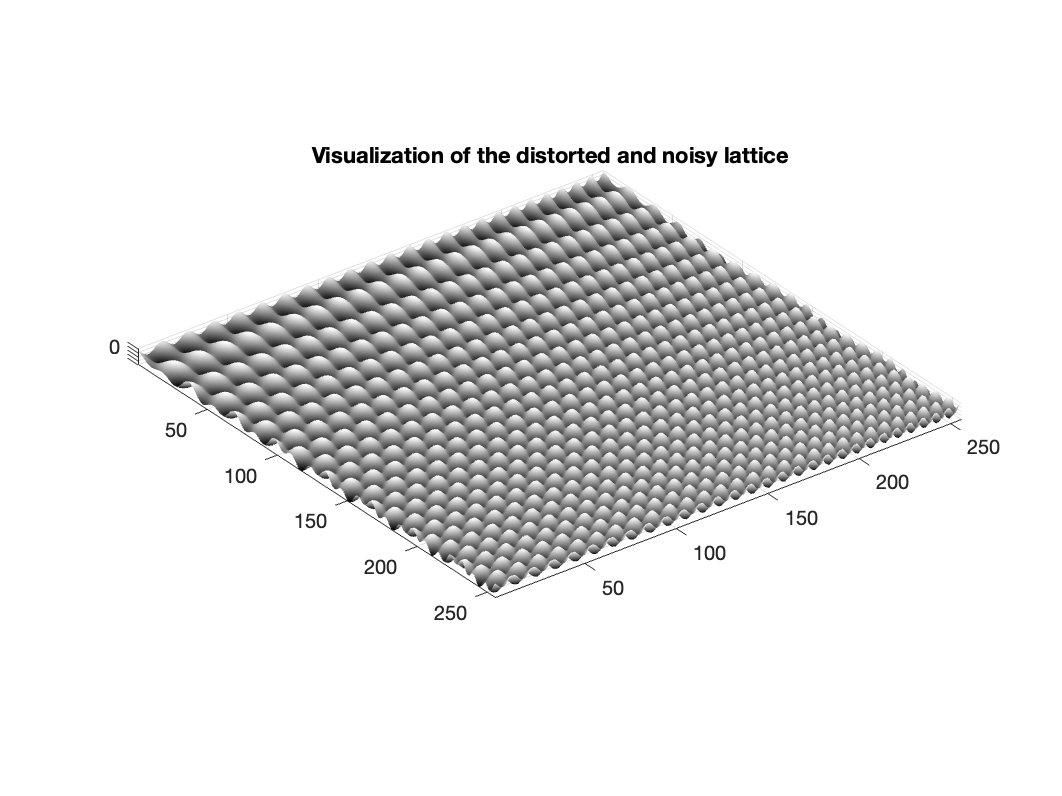


surf(nlattice);
shading interp;
axis equal;
set(gca,"YDir","reverse");
colormap(gray);
title("Visualization of the distorted and noisy lattice");

## 3    Calculating total distortion

tic
ucalc = myConv(lattice,Q_x,Q_y,lambda,zscore,true); % true as last argument to plot u_x and u_y
toc

Elapsed time is 0.590704 seconds.


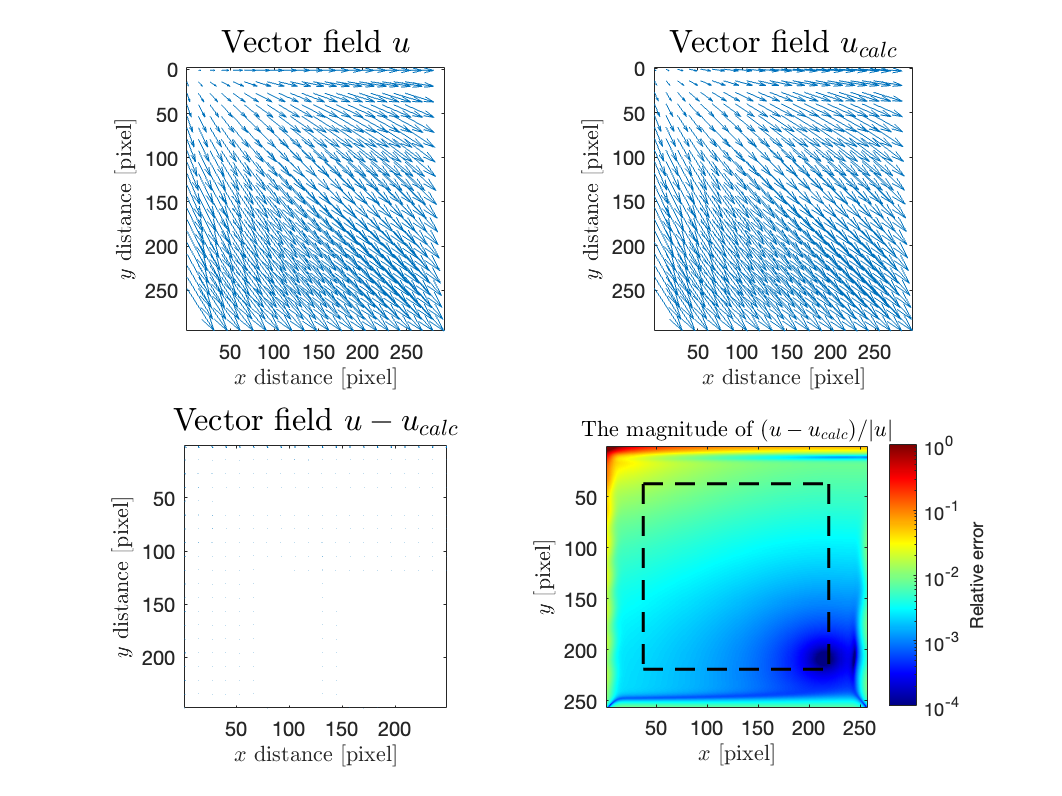


% latx = squeeze(u(:,:,1));
% laty = squeeze(u(:,:,2));
% 
% pa = -unwrapGoldstein(exp(-1i*(Q_x(1)*latx+Q_x(2)*laty)));
% pb = -unwrapGoldstein(exp(-1i*(Q_y(1)*latx+Q_y(2)*laty)));
% 
% ucalc = zeros(size(u));
% ucalc(:,:,1) = (pa*Q_y(2)-pb*Q_x(2))./(Q_x(1)*Q_y(2)-Q_y(1)*Q_x(2));
% ucalc(:,:,2) = (pa*Q_y(1)-pb*Q_x(1))./(Q_x(2)*Q_y(1)-Q_y(2)*Q_x(1));

uComboPlot(u,ucalc,lambda,zscore);


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 33124 (50.5432%)



[meanErr, stdErr] = uCompare(u,ucalc,lambda);
disp("Error is: " + meanErr + "+/-" + stdErr*zscore + " (" + confidence_level*100 + "% confidence)");

Error is: 0.0039651+/-0.022226 (100% confidence)


disp("Total error is: " + (meanErr+stdErr*zscore) + " (" + confidence_level*100 + "% confidence)");

Total error is: 0.026191 (100% confidence)


disp("Errors are relative unless stated otherwise.");

Errors are relative unless stated otherwise.


## 4    Calculating physical strain

[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore);

% fitPlot(fitresultx, ucalc(:,:,1), "$u_x$", lambda,zscore);
[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore);

% fitPlot(fitresulty, ucalc(:,:,2), "$u_y$", lambda,zscore);

resx = reshape(outputx.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
mu = mean(resx,"all")/atom_diameter; % [lattice constant]
sigma = std(resx,1,"all")/atom_diameter; % [lattice constant]

resy = reshape(outputy.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
mu(2) = mean(resy,"all")/atom_diameter; % [lattice constant]
sigma(2) = std(resy,1,"all")/atom_diameter; % [lattice constant]

[xi,yi] = meshgrid(1:image_length,1:image_height);
convPlot(ucalc(:,:,1)-fitresultx(xi,yi),"calculated physical strain",ucalc(:,:,2)-fitresulty(xi,yi),lambda,zscore);

disp("Physical strain along x = " + (sigma(1)) + " [lattice constant]");

Physical strain along x = 0.00075353 [lattice constant]


disp("Physical strain along y = " + (sigma(2)) + " [lattice constant]");

Physical strain along y = 0.00098339 [lattice constant]
